# Code-gen Supported alternate for Griddata.

This is just a sample problem. We have some 3d data with no discernable mathematical connections. Particularly this sample this data is even more scattered than the example showed.

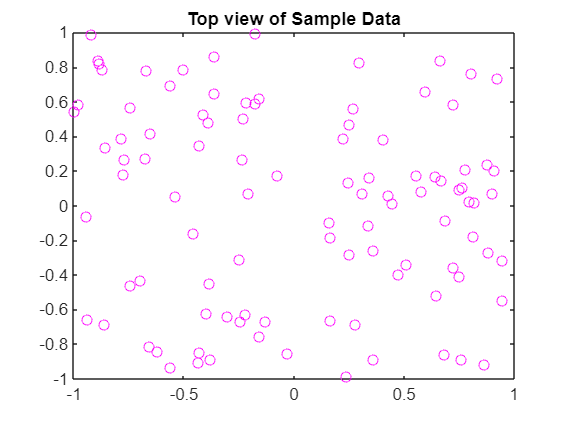

clear
load data.mat
plot(x,y,'mo')
title('Top view of Sample Data')

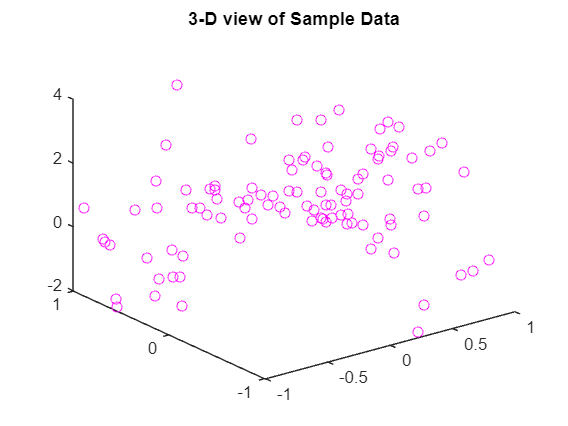

plot3(x,y,z,'mo')
title('3-D view of Sample Data')

This is how you would interpolate using griddata.

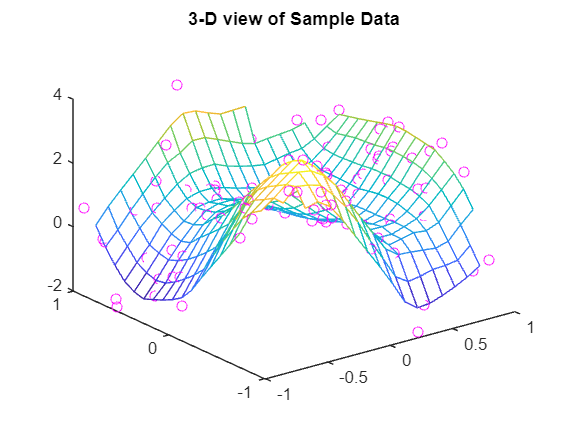

[xq,yq] = meshgrid(-1:0.1:1,-1:0.1:1);
plot3(x,y,z,'mo')
title('Interpolation using griddata')
hold on
zq = griddata(x,y,z,xq,yq);
mesh(xq,yq,zq)
hold off;

To use the interpX, simply call it as you would griddata.

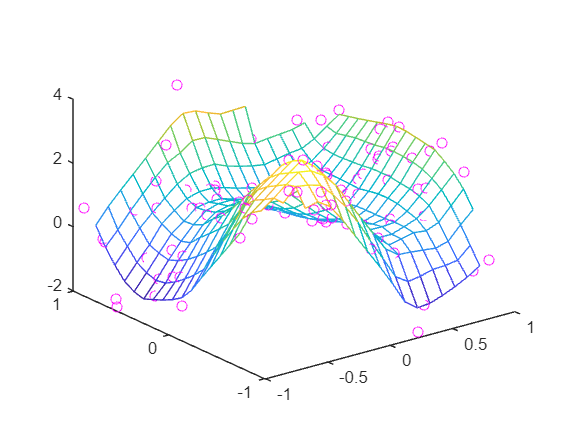

zn = interpX(x,y,z,xq,yq);
plot3(x,y,z,'mo')
title('Interpolation using interpX')
hold on
mesh(xq,yq,zn)
hold off;


RMSE = mean((zq-zn).^2,'all','omitnan' )

RMSE = 2.9495e-31